# DEV

## Clear workspace and close figure windows

clear; clc;
close all force;


## Create a rat object containing all the experiments for R19-160

R19-160 had sensory evoked forelimb activity in both hemispheres on the first insertion attempt for each electrode array. Combinations of solenoid-evoked cutaneous activity and intracortical microstimulation (ICMS) modulation of that activity were used to study the influence of ICMS on the evoked sensory responses of rat cortex. This will be qualitatively helpful in understanding the influence of activity-dependent stimulation (ADS) upon ongoing activity in forelimb sensory cortex of the rat, and in turn in understanding why ADS is helpful during behavioral rehabilitation from brain injury. 

r = solRat('P:\Rat\RegionSpecificity\R19-160');

## Create an experimental block for double-tap 10ms experiment

In this block (R19-160, block # 33), the solenoid was placed to strike the **right **paw in two quick taps of 10ms duration, with 40ms from the end of the first tap to the onset of the second tap. No intracortical microstimulation (ICMS) was delivered. 

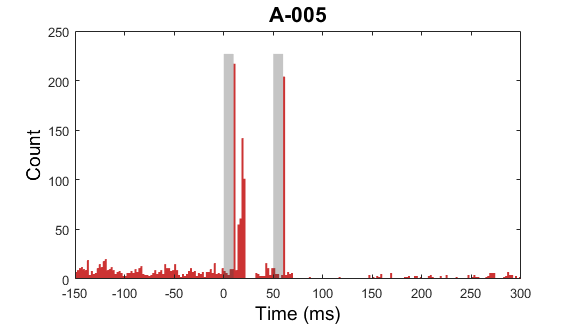

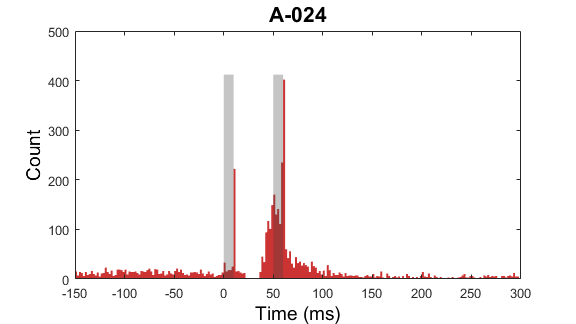

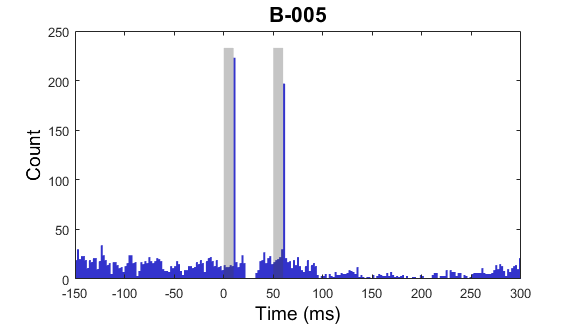

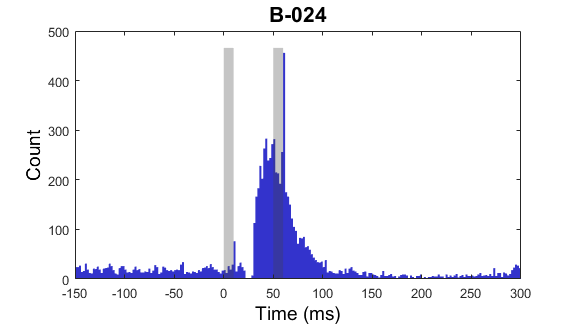


% b = solBlock('P:\Rat\RegionSpecificity\R19-160\R19-160_2019_08_07_33');
b = r.Children(34); % experiments are 0-indexed by label

## Generate peri-event time histograms of spiking for that experiment

We will look at only a subset of the channels, initially. Channels A-005, A-024, B-005, and B-024 were all stimulated (each port is zero-indexed). Channel 005 is in layer 2/3, while channel 024 is in layer 5 for each probe. 

This dataset has already had the spikes extracted. We will plot the peri-event time histogram (PETH), showing how many spikes were evoked after all 200 experimental trials, between 150 ms (-0.150 seconds) prior to the trial trigger (DIG-OUT1), and 300 ms (0.300 seconds) after the trial trigger, in 2 ms (0.002 seconds) bins. 

PETH(b,-0.150,0.300,0.002,[6,25,38,57]); % select STIM'd channels


In this case, the solenoid is expected to evoke a robust response in the **left **hemisphere (probe **A**). Notice that at a latency of 19ms, there is a peak in L2/3 that is not as evident in L5 of this hemisphere, and is not present in either of the channels of probe **B **(right hemisphere). 

A second peak, at 51 ms, is present in L5 of the **left **hemisphere. Two such later peaks are also evident in L5 of the **right **hemisphere, at both 41 ms and 51 ms.